clc; clear; close all;

%% --- Davenport Spectrum parameters ---
U = 3.15;            % mean wind speed (m/s)
z = 23.16;           % antenna height (m)
z0 = 0.03;           % roughness length (m)

b = 600 / (pi * U);
k = (1 / (2.5 * log(z / z0)))^2;

f = linspace(0.001, 3, 2000);   % frequency vector (Hz)
w = 2*pi*f;                     % angular frequency (rad/s)

Sv = (4800 * U * b * k) ./ ((1 + (b^2) * w.^2).^(4/3));   % Davenport PSD

%% --- Continuous-time TF H_fit(s) ---
num_c = [0.01197  0  -40.03   0  461.3];    % coefficients for s^4 ... s^0
den_c = [1        0  -482.7   0   65.13];   % coefficients for s^4 ... s^0

% Display transfer function in MATLAB-friendly format
H_fit = tf(num_c, den_c);  
disp('Continuous-time transfer function H_fit(s):');

Continuous-time transfer function H_fit(s):


H_fit

H_fit =
 
  0.01197 s^4 - 40.03 s^2 + 461.3
  -------------------------------
      s^4 - 482.7 s^2 + 65.13
 
Continuous-time transfer function.
Model Properties


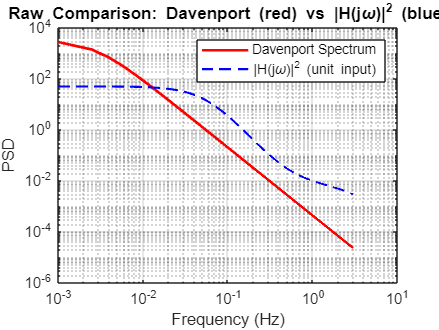


% Compute frequency response of analog TF at frequencies w
Hjw = freqs(num_c, den_c, w);   % Hjw is complex frequency response H(jw)

% Theoretical output PSD for unit-spectral-level white noise: S_out(w) = |H(jw)|^2
PSD_H = abs(Hjw).^2;

%% --- Option A: Raw comparison ---
figure('Name','Raw PSD comparison');
loglog(f, Sv, 'r-', 'LineWidth', 1.8); hold on;
loglog(f, PSD_H, 'b--', 'LineWidth', 1.4);
grid on;
xlabel('Frequency (Hz)');
ylabel('PSD');
title('Raw Comparison: Davenport (red) vs |H(j\omega)|^2 (blue)');
legend('Davenport Spectrum','|H(j\omega)|^2 (unit input)');

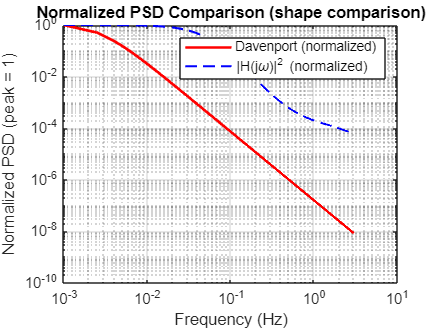


%% --- Option B: Normalized comparison ---
PSD_H_norm = PSD_H / max(PSD_H);
Sv_norm = Sv / max(Sv);

figure('Name','Normalized PSD comparison');
loglog(f, Sv_norm, 'r-', 'LineWidth', 1.8); hold on;
loglog(f, PSD_H_norm, 'b--', 'LineWidth', 1.4);
grid on;
xlabel('Frequency (Hz)');
ylabel('Normalized PSD (peak = 1)');
title('Normalized PSD Comparison (shape comparison)');
legend('Davenport (normalized)','|H(j\omega)|^2 (normalized)');

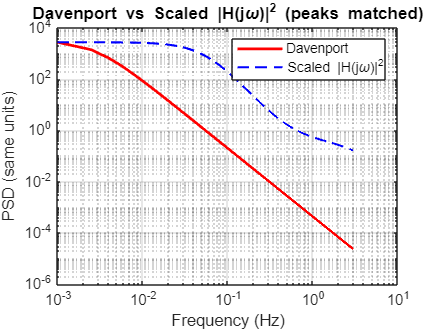


%% --- Option C: Scaled TF PSD to match Davenport peak ---
scale_factor = max(Sv) / max(PSD_H);   
PSD_H_scaled = PSD_H * scale_factor;

figure('Name','Scaled PSD comparison');
loglog(f, Sv, 'r-', 'LineWidth', 1.8); hold on;
loglog(f, PSD_H_scaled, 'b--', 'LineWidth', 1.4);
grid on;
xlabel('Frequency (Hz)');
ylabel('PSD (same units)');
title('Davenport vs Scaled |H(j\omega)|^2 (peaks matched)');
legend('Davenport','Scaled |H(j\omega)|^2');


%% --- Display peak info ---
[~, idx_Sv_peak] = max(Sv);
f_Sv_peak = f(idx_Sv_peak);
Sv_peak = Sv(idx_Sv_peak);

[~, idx_H_peak] = max(PSD_H);
f_H_peak = f(idx_H_peak);
H_peak = PSD_H(idx_H_peak);

fprintf('Davenport peak: f = %.4f Hz, value = %.4e\n', f_Sv_peak, Sv_peak);

Davenport peak: f = 0.0010 Hz, value = 2.7694e+03


fprintf('TF    peak:      f = %.4f Hz, value = %.4e\n', f_H_peak, H_peak);

TF    peak:      f = 0.0010 Hz, value = 5.0136e+01


fprintf('Scale factor used (to match peaks): %.4e\n', scale_factor);

Scale factor used (to match peaks): 5.5237e+01
